% Calculation 


# 数值微分和数值积分

## diff & ca


$$\mathrm{f'}\left(x\right)=f\left(x+h\right)-\frac{f\left(x\right)}{h},h\to 0$$



$$\Delta \;f\left(x_{0\;} \right)=f\left(x_0 +h\right)-f\left(x_0 \right)$$



$$\triangleleft f\left(x_0 \right)=f\left(x_0 \right)-f\left(x_0 -h\right)$$



$$\delta \;f\left(x_0 \right)=f\left(x_0 +\frac{h}{2}\right)-f\left(x_{0\;} -\frac{h}{2}\right)$$


## diff()

若


$$\mathrm{dx}\;=\;\mathrm{diff}\left(x\right)$$


则$\mathrm{dx}\left(i\right)=x\left(i+1\right)-x\left(i\right)$

即向前差分

若$\textrm{dx}\;=\;\textrm{diff}\left(\mathrm{x，}\;n\right)$

则得到n阶向后差分

如


$$\mathrm{dx}\;=\;\mathrm{diff}\left(x,2\right)=\mathrm{diff}\left(\mathrm{diff}\left(x\right)\right)$$


有 $\mathrm{dx}\left(i\right)=x\left(i+2\right)-2x\left(i+1\right)+x\left(i\right)$

t = 1:10+rem(rand(1, 10)*10, 2);
dt = diff(t);
d2t = diff(t, 2);
if all(diff(dt) == d2t)
    disp("diff(dt) == d2t")
end

diff(dt) == d2t



disp(t);

     1     2     3     4     5     6     7     8     9    10



disp('dt:');

dt:


disp(dt);

     1     1     1     1     1     1     1     1     1



disp('{d^2}t:');

{d^2}t:


disp(d2t);

     0     0     0     0     0     0     0     0



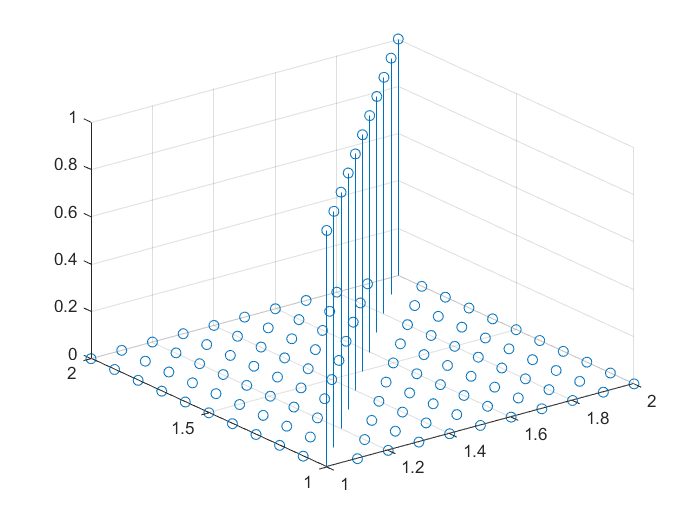

[x, y] = meshgrid(1:.1:2);
z = eye(size(x));
stem3(x, y, z)

times = 10;
start_v = 0;
step=.2;
demo_func = @(x) x.*x

demo_func = 包含以下值的 function_handle :
    @(x)x.*x


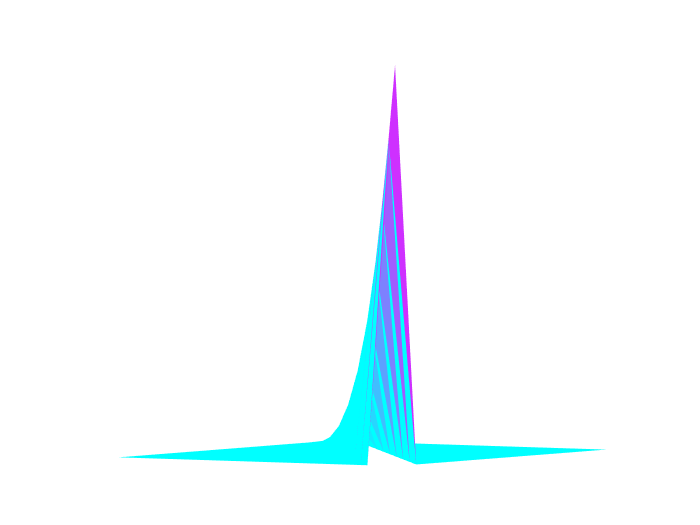

[x, y] = meshgrid(start_v:step:start_v+step*times, 1:times+1);

z=diag(demo_func(start_v:step:start_v+step*times));

surf(x, y, z)
colormap('cool')
axis off
grid off
shading flat

view([122.50 2.80])